# **INSTITUTO TECNOLÓGICO DE AERONÁUTICA **

# **CCI-22 - Professor Victor Curtis **

# **Pedro Luchiari de Carvalho - Turma 4 **

# **Relatório 5 - Interpolação (parte 2)**

## Questão 1 

%cálculo dos nós de Chebyshev:
n=2;
a=-3;
b=3;
for i = 0 : n
    xc(i+1) = cos(pi*i/n);
end

for i = 0:n
    x(i+1) = (a+b)*0.5 - (b-a)*0.5*xc(i+1);
end

fprintf('nos de Chebyshev:')

nos de Chebyshev:

for i=1:n+1
    fprintf('x%d = %.5f.\n',i-1, x(1,i));
end

x0 = -3.00000.
x1 = -0.00000.
x2 = 3.00000.



%Agora vem a interpolação (usaremos a função polyfit). O output serão os coeficientes 
% do nosso polinômio, que serão usados na subsequente plotagem:
y = arrayfun(@(x) f(x), x);
l = linspace(-3,3);
p = polyfit(x, y, n);

fplot(@(l) polyval(p, l), [-3, 3])
hold on
fplot(@(l) f(l), [-3, 3])

grid on
title('Interpolação para grau 2')
xlabel('x');
ylabel('y');
legend('p(x)', 'f(x)');

maxerror = 0;
for i = 1:100
    if polyval(p, l(i))-f(l(i)) > maxerror
       maxerror = polyval(p, l(i))-f(l(i));
    end
end

display (maxerror);

maxerror = 0.1319

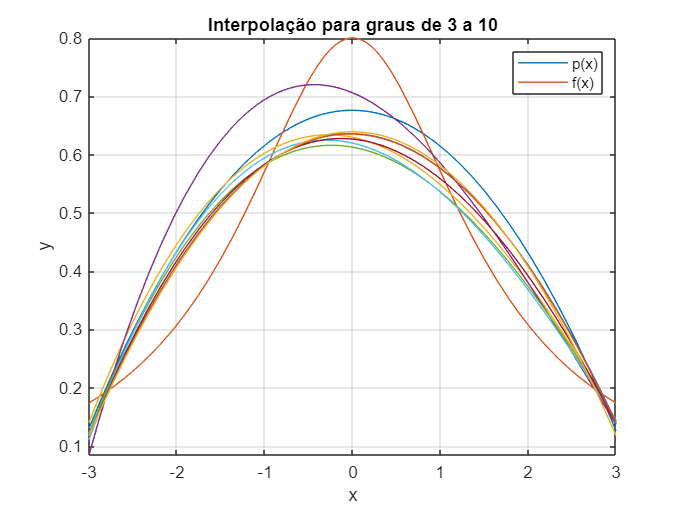

nos de Chebyshev para n = 3:

x0 = -3.00000.
x1 = -1.50000.
x2 = 1.50000.


nos de Chebyshev para n = 4:

x0 = -3.00000.
x1 = -2.12132.
x2 = -0.00000.


nos de Chebyshev para n = 5:

x0 = -3.00000.
x1 = -2.42705.
x2 = -0.92705.


nos de Chebyshev para n = 6:

x0 = -3.00000.
x1 = -2.59808.
x2 = -1.50000.


nos de Chebyshev para n = 7:

x0 = -3.00000.
x1 = -2.70291.
x2 = -1.87047.


nos de Chebyshev para n = 8:

x0 = -3.00000.
x1 = -2.77164.
x2 = -2.12132.


nos de Chebyshev para n = 9:

x0 = -3.00000.
x1 = -2.81908.
x2 = -2.29813.


nos de Chebyshev para n = 10:

x0 = -3.00000.
x1 = -2.85317.
x2 = -2.42705.



%Agora, aplicaremos o mesmo para n = 3 : 10

for i = 3:10
    for j = 0:i
        xc(j+1) = cos(pi*j/i);
    end
    for j = 0:i
        x(j+1) = (a+b)*0.5 - (b-a)*0.5*xc(j+1);
    end
    fprintf('nos de Chebyshev para n = %d:', i)
    for i=1:n+1
        fprintf('x%d = %.5f.\n',i-1, x(1,i));
    end
    y = arrayfun(@(x) f(x), x);
    p = polyfit(x, y, i);
    fplot(@(l) polyval(p, l), [-3, 3])
    grid on
    title('Interpolação para graus de 3 a 10')
    xlabel('x');
    ylabel('y');
    legend('p(x)', 'f(x)');
end

Definição da função f:

function d = f(x)
    d = 4/(5+2*x^2);
end

## Questão 2